# Stress Strain Revisited

- Demonstrate using non-linear regression (`nlfit)` to identify the parameters of the Ramberg-Osgood model to fit the empirical stress-strain data given in Assignment 7.

- The interface for [`nlinfit`](https://www.mathworks.com/help/stats/nlinfit.html#btk7ign-options) can provide the final MSE for the model fit to quantify the goodness-of-fit.  

- Include a figure to show the data and the model prediction, with appropriate labels, units, legend, etc.   Somewhere in the figure include the value of the MSE for the fit.

% Strain [mm/mm]
strain_exp = [0, 0.0023809 0.003749347, 0.005234888, ...
    0.007631515, 0.011446096, 0.017384888, ...
    0.026405375, 0.039775799];
% Stress [MPa]
stress_exp = [0, 500, 550, 600, 660, 720, 780, 840, 900];

Define a model function

One model that we can use to explain the data is the Ramberg-Osgood equation:


$$\epsilon = \frac{\sigma}{E} + \left(\frac{\sigma}{K}\right)^n$$


The Young's modules for the material is known:


$$E = 210,000 \:\: \text{MPa}$$


We can reuse our function our ROE function from Assignment 7.

function strain = ROE_model(params, stress)
    K = params(1);

strain =          0    0.0336    0.0529    0.0806    0.1284    0.1969    0.2924    0.4222    0.5948


    n = params(2);
    E = 210000;
    strain = stress./E + (stress./K).^n;
end

beta = 1.0e+03 *

    1.4801    0.0067


R = 1.0e-03 *

         0
   -0.6891
   -0.1757
    0.0366
    0.0515
    0.0633
    0.0626
    0.0338
   -0.0484


J =          0         0
   -0.0000   -0.0007
   -0.0000   -0.0013
   -0.0000   -0.0021
   -0.0000   -0.0036
   -0.0000   -0.0057
   -0.0001   -0.0087
   -0.0001   -0.0127
   -0.0002   -0.0177


CovB =   116.3572   -0.9636
   -0.9636    0.0081


MSE = 7.4449e-08

ErrorModelInfo = struct with fields:
              ErrorModel: 'constant'
         ErrorParameters: 2.7285e-04
           ErrorVariance: @(x)mse*ones(size(x,1),1)
                     MSE: 7.4449e-08
          ScheffeSimPred: 3
          WeightFunction: 0
            FixedWeights: 0
    RobustWeightFunction: 0


Test your function with nominal values of $K = 1000$ MPA and $n = 7$.  First test for a scalar value of stress, say 500 MPA.

params0 = [1000, 5];
strain = ROE_model(params0, stress_exp)

Call nlfit

[beta,R,J,CovB,MSE,ErrorModelInfo] = ...
    nlinfit(stress_exp, strain_exp, @ROE_model, params0)

Plot

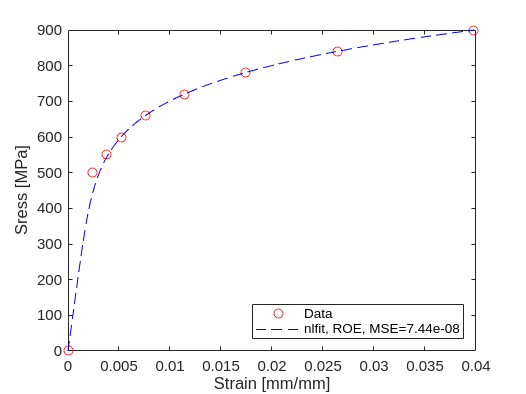

figure;
clf;
plot(strain_exp, stress_exp, 'ro', "DisplayName", "Data")
hold on
stress = linspace(min(stress_exp), max(stress_exp), 100);
strain_model = ROE_model(beta, stress);
plot(strain_model, stress, 'b--', "DisplayName",...

    sprintf("nlfit, ROE, MSE=%.2e", MSE))
xlabel("Strain [mm/mm]")
ylabel("Sress [MPa]")
legend('Location','southeast')

fminsearch: 	 K = 1480.100 [MPa], n = 6.7082918, MSE = 5.21e-07 [mm/mm] 


Compare nlfit and fminsearch

Our output from Assignment 7

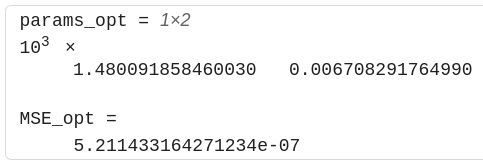

fprintf("fminsearch: \t K = %.3f [MPa], n = %.7f, MSE = %.2e [mm/mm] \n", ...
    1480.1, 6.70829176, 5.21143e-7);

nlfit: 		 K = 1480.092 [MPa], n = 6.7082914, MSE = 7.44e-08 [mm/mm] 


fprintf("nlfit: \t\t K = %.3f [MPa], n = %.7f, MSE = %.2e [mm/mm] \n", ...
    beta(1), beta(2), MSE);

The two algorihms provide similar results.  The nlfit algorithm provides an imporoved model with an improved goodness-of-fit as measured by MSE.  It seems reasonable that a customized algorithm, designed specifically for nonlinear regression would perform better than a more generic solver applied to the specific problem of least-squares regression.